clear all, close all, clc


## NOTE CURRENTLY MOst COEFFICIENT DO NOT UPDATE lateral dynamics not implemented

## TODO add nonlinear spring to act as stop on flap throw

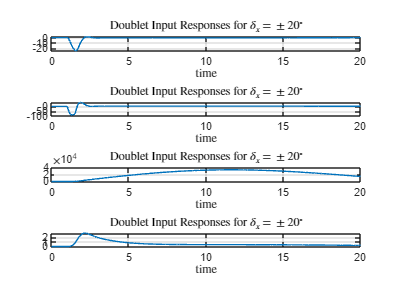


% define IC and controls
dt = .01;
time = [0:dt:20]';
angle = 20;
t_0 = 1;
t_end = length(time);

throttle = zeros(size(time));
elevator = zeros(size(time));
aileron = zeros(size(time));
rudder = zeros(size(time));
elevator(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180;

k = ones(size(time)) .* .02; % PAH spring const
c_r = ones(size(time)) .* .05; % rate damping coefficient (N*s/rad^2)
delta_0 = ones(size(time)) .* 0; % colombic damping coefficient (N)p


% elevator(1.5/dt:2/dt) = ones(size(1.5/dt:2/dt)).*angle.*-pi./180.;
% elevator = elevator  + .003*randn(size(elevator));
VT = zeros(size(time));
VT(1) = 220.1;
Alphaest = zeros(size(time));
Betaest = zeros(size(time));
phi = zeros(size(time));
theta = zeros(size(time));
psi = zeros(size(time));
P = zeros(size(time));
Q = zeros(size(time));
R = zeros(size(time));
ned = [zeros(size(time)),zeros(size(time)),zeros(size(time))];
delta_f = 0; % inital flap position
delta_f_dot = 0; % initial flap rate

cv = [throttle,   elevator ,   aileron  ,   rudder, k, c_r, delta_0 ];
X_0 = [VT(1), Alphaest(1), Betaest(1), phi(1), theta(1), psi(1), ...
    P(1), Q(1), R(1), ned(1,1), ned(1,2), -ned(1,3), throttle(t_0), elevator(t_0) , ...
    aileron(t_0) , rudder(t_0),...
    delta_f, delta_f_dot];

y = X_0;

%initialize y_all and t_all with IC as first element
y_all = zeros([length(t_0:t_end),18]);       t_all = zeros([length(t_0:t_end),1]);
y_all(1,:) = y;     t_all(1) = time(t_0);       J = 2;

for i = (t_0):(length(time)-1)
    cv1 = cv(i,:); %update control inputs and time span for ODE45 each iteration
    tspan = [time(i) time(i+1)];       dt = time(i+1) - time(i);
    [t,y] = ode45(@(t,y) aircraft(t,y,cv1), tspan, X_0);
    X_0 = y(size(y, 1),:);  % set new IC as ending state
    t_all(J) = t(end);       y_all(J,:) = y(end,:);
    J = J + 1; % indexer for recording y and t
end

%Convert to deg
y_all(:,2:end) = y_all(:,2:end)*180/pi;


var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'delta_f', 'delta_f_dot', 'throttle', 'elevator', 'aileron', 'rudder'};

% Plot Longitudinal variables (VT, VT_guid, theta, theta_guid, Q, del_t, del_e)
for ii = 1:length(var_guid)
    Vname{ii} = y_all(:,ii);
end

figure
ii = 0;
for i = [2,8,12,17] %7,9
    ii = ii + 1;
    subplot(4,1,ii)
    plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    title(['Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
end

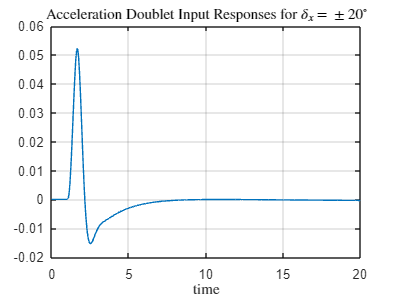


figure
plot(time(1:end-1),diff(Vname{i})), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
title(['Acceleration Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')


% ii=0;
% for i = [3 4 6 7 9, 15]
%     ii = ii + 1;
%     subplot(3,2,ii)
%     plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
% end
% sgtitle(['Lat. Doublet Input Responses for $\delta_a$ = ', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
% 




function Xdot = aircraft(t, y, cv, stab_cont_derivs)

i = 1;
states = y;
controls = cv;

VT      = states(0+i); %long
alpha   = states(1+i); %long
beta    = states(2+i);

phi     = states(3+i);
theta   = states(4+i); % long
psi     = states(5+i);

P       = states(6+i);
Q       = states(7+i); %long
R       = states(8+i);

% Initial Control surfaces
del_t_x   = states(12+i);
del_e_x   = states(13+i);
del_a_x   = states(14+i);
del_r_x   = states(15+i);

% PAH flap states
del_f  = states(16+i);
del_f_dot  = states(17+i);

% Control inputs
del_t   = controls(0+i);
del_e   = controls(1+i);
del_a   = controls(2+i);
del_r   = controls(3+i);

% PAH control inputs
k = controls(4+i);
c_r = controls(5+i);
delta_0 = controls(6+i);
c_c = 0.005;

u = VT*cos(alpha)*cos(beta);
v = VT*sin(beta);
w = VT*sin(alpha)*cos(beta);

% Constants
g = 32.14741; %ft/s2 %g*3.2808399;

% Trim values
alphatrim = 0; % convert input trim to rad
Ptrim        = 0; %(rad/s)
Qtrim        = 0; %(rad/s)
Rtrim        = 0; %(rad/s)
VTtrim       = 220.1; %(ft/s)
utrim        = VTtrim*cos(alphatrim); %(ft/s)

S    = 174; %(ft2)
cbar = 4.9; %(ft)
b    = 36; %(ft)
AR   = 7.448;
mass = 2650; %(lbm)
I_xx = 948; %(slug-ft2)
I_yy = 1346; %(slug-ft2)
I_zz = 1967; %(slug-ft2)
I_xz = 0.00; %(slug-ft2)

% Flap parameters
c_f = .25; % flap cord (m)
C_h_0 = 0; % 0 angle of attack 0 deflection hinge moment (~)
C_h_alpha = -.45; % control surface hinge moment deriveative due to angle of attack (~)
C_h_delta = -.85; % control surface moment derivative due to flap deflection (~)
% location of Flap 
r_f_i = [0; -1; 0]; % distance in body coordinates from the aircraft centre of gravity to the inboard most section of the control surface hingeline (m)
r_f_o = [0; 1; 0]; % distance in body coordinates from the aircraft centre of gravity to the outboard most section of the control surface hingeline (m)
r_f_i_TE = [-1; -1; 0]; % distance in body coordinates from the aircraft centre of gravity to the trailing edge of the inboard most section of the undeflected control surface (m)
r_f_cg_B = [0; 0; 0]; % distance in body coordinates from the aircraft centre of gravity to the location of the hingleline at the section of flap contining its centre of gravity (m)


% aircraft coefficients
c_l_alpha_wf = 2*pi; % lift coefficient of wing fuselage combination per radian (1/radian)
c_l_alpha_h = 2*pi; % lift coefficient of wing fuselage combination per radian (1/radian)
tau_delta_f = .45; % efficiency of flap (~) from roskam stability and control part 1 page 61 figure 2.23
eta_h = .9; % dynamic pressure ratio of horizontal tail to free stream (~)
S_h = 1.75; % horizontal tail planform area (m^2)
d_elpsilon_d_alpha_h = .111; % downwash gradient on the horizontal tail (1/radians) from AAA (can also compute using roskam part 6 page 262)
I_h = .9;

% Stop spring range and coeffcient
delta_min = -deg2rad(20); % minimum deflection angle (radians)
delta_max = deg2rad(20); % maximum deflection angle (radians)
k_stop = 1000; % deflection limiting hardening spring stiffness N/(m^2)

% Note to self: flip flap limits for left aeileron because positive and
% negative may be flipped

% steady state

C_L1  = 0.307;
C_m1  = 0.0;
C_mt1 = 0.0;

% S&C derivatives
C_D0bar   = 0.032;
e=.75;

C_yda     = 0;
C_Lq      = 3.9;
C_Ladot   = 1.7;
C_mtu     = 0;
C_mtalpha = 0;
C_yb      = -.393;      C_yp      = -.075;
C_yr      = .214;       C_La      = 4.41;
C_Lu      = 0;          C_lb      = -.0923;
C_lp      = -.484;      C_lr      = .0798;
C_ma      = -.613;      C_mq      = -12.4;
C_madot   =-7.27 ;      C_mu      = 0;
C_nb      = .0587;      C_np      = -.0278;
C_nr      = -.0937;     C_ydr     = .187;
C_ldela   = .229;       C_ldelr   = .0147;
C_ndela   = -.0216;     C_ndelr   = -.0645;
C_Ldele   = .43;        C_mdele   = -1.122;
C_yda     = 0;
C_mtu     = 0;
C_mtalpha = 0;

mass = mass/g; % lbm to slug
rho  = 0.002048;
qbar = 0.5*rho*(VT^2);

% aero forces and moment
C_L  = C_L1 + C_La*(alpha - alphatrim) + (C_Lq*(Q - Qtrim)*(cbar/2))/utrim + (C_Lu*(u - utrim))/utrim + C_Ldele*(del_e_x ) + C_La* tau_delta_f * del_f; % be careful with sign of flap deflection for left flap
C_D  = C_D0bar + (C_L^2)/(pi*AR*e); % flap drag not implemented

C_Y  = C_yb*beta + (C_yp*(P - Ptrim)*(b/2))/utrim + (C_yr*(R - Rtrim)*(b/2))/utrim + C_yda*del_a_x + C_ydr*del_r_x;
C_ls = C_lb*beta + (C_lp*(P - Ptrim)*(b/2))/utrim + (C_lr*(R - Rtrim)*(b/2))/utrim + C_ldela*del_a_x + C_ldelr*del_r_x;
C_ms = C_m1 + C_ma*(alpha - alphatrim) + (C_mq*(Q - Qtrim)*(cbar/2))/utrim + (C_mu*(u - utrim))/utrim + C_mdele*(del_e_x ) + ...
    2*(C_m1*(u - utrim))/utrim + (C_mtu + 2*C_mt1)*(u - utrim)/utrim + C_mtalpha*(alpha - alphatrim);


% note: flap moment negigible
C_ns = C_nb*beta + (C_np*(P - Ptrim)*(b/2))/utrim + (C_nr*(R - Rtrim)*(b/2))/utrim + C_ndela*(del_a_x) + C_ndelr*del_r_x;
C_xa = C_L*sin(alpha) - C_D*cos(alpha);
C_ya = C_Y;
C_za = -C_L*cos(alpha) - C_D*sin(alpha);
C_l  = C_ls*cos(alpha) - C_ns*sin(alpha);
C_m  = C_ms;
C_n  = C_ls*sin(alpha) + C_ns*cos(alpha);

%Thrust model
%???????????????????????????????????????????????????????????????????????????????????????????????
T = 322.5669;

% grav accel
g_x = -g*sin(theta);
g_y = g*sin(phi)*cos(theta);
g_z = g*cos(phi)*cos(theta);

% body accel
a_x = (qbar*S*C_xa + T)/mass;
a_y = (qbar*S*C_ya)/mass;
a_z = (qbar*S*C_za)/mass;

% moment
L = C_l*qbar*S*b;
M = C_m*qbar*S*cbar;
N = C_n*qbar*S*b;
% Differential equations:
% Body linear velocities
udot = a_x + g_x + R*v - Q*w;
vdot = a_y + g_y - R*u + P*w;
wdot = a_z + g_z + Q*u - P*v;

% Total velocity and airflow angles
VTdot    = (u*udot + v*vdot + w*wdot)/VT;
alphadot = (u*wdot - w*udot)/((u^2) + (w^2));
betadot  = ((VT*vdot - v*VTdot)/((u^2) + (w^2)))*cos(beta);
%betadot  = (vdot*((u^2) + (w^2)) - v*(u*udot + w*wdot))/((VT^2)*(sqrt((u^2) + (w^2))));



% Body angular velocities
Pdot = (I_zz*L + I_xz*N - (I_xz*(I_yy - I_xx - I_zz)*P + ((I_xz^2) + I_zz*(I_zz - I_yy))*R)*Q)/(I_xx*I_zz - (I_xz^2));
Qdot = (M - (I_xx - I_zz)*P*R - I_xz*((P^2) - (R^2)))/I_yy;
Rdot = (I_xz*L + I_xx*N + (I_xz*(I_yy - I_xx - I_zz)*R + ((I_xz^2) + I_xx*(I_xx - I_yy))*P)*Q)/(I_xx*I_zz - (I_xz^2));

% Inertial (Euler) angles
phidot   = P + (R*cos(phi) + Q*sin(phi))*tan(theta);
thetadot = Q*cos(phi) - R*sin(phi);
psidot   = (Q*sin(phi) + R*cos(phi))/cos(theta);

% Inertial position dynamics
x_Idot = (cos(theta)*cos(psi))*u + (-cos(phi)*sin(psi) + sin(phi)*sin(theta)*cos(psi))*v + (sin(phi)*sin(psi) + cos(phi)*sin(theta)*cos(psi))*w;
y_Idot = (cos(theta)*sin(psi))*u + (sin(phi)*sin(theta)*sin(psi) + cos(phi)*cos(psi))*v + (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*w;
z_Idot = (-sin(theta))*u + (sin(phi)*cos(theta))*v + (cos(phi)*cos(theta))*w;

% Control surface dynamics
Athrottle=-7;
Bthrottle=7;
Aelevator=-30;
Belevator=30;
Aaileron=-30;
Baileron=30;
Arudder=-30;
Brudder=30;

del_tdot = Athrottle*del_t_x + Bthrottle*del_t;
del_edot = Aelevator*del_e_x + Belevator*del_e;
del_adot = Aaileron*del_a_x + Baileron*del_a;
del_rdot = Arudder*del_r_x + Brudder*del_r;

% get flap angle
q_bar = 1/2 * rho * VT^2; % dynamic pressure (Pa)
% 
% determine prefered damping constant
% set c_r for airfoil responce properties
zeta = .7; % damping ratio
mu = 4*I_h* (q_bar * c_f^2 * C_h_delta - k); % airfoil responce parameter
% set damping to make that true (note culombic damping will be suboptimal
c_d = 2*I_h*zeta * sqrt(-mu * (2*I_h*zeta - 1) * (2*I_h*zeta + 1)) / (4*I_h^2*zeta^2-1); % total damping coefficient
% unsure if i should use the one that acounts for culombic damping (good
% near fp) or the one that doesn't (good far from f.p.) I think that as
% this is transient responce culombic damping should be acounted for
c_r = max(c_d - c_c,0);

% Adaptive_Airfoil_Dynamics is outdated 
%df = Adaptive_Airfoil_Dynamics(t, [del_f, del_f_dot], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, alpha, q_bar);
df = Adaptive_Aerocompliant_Airfoil_Dynamics(t, [del_f, del_f_dot], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i, r_f_o, r_f_i_TE, r_f_cg_B, rho, [u;v;w], [P;Q;R]);
del_f_dot = df(1);
del_f_dotDot = df(2);


Xdot = [VTdot; alphadot; betadot; phidot; thetadot; psidot; Pdot; ...
    Qdot; Rdot; x_Idot; y_Idot; z_Idot; del_tdot; del_edot; del_adot; del_rdot; del_f_dot; del_f_dotDot];

end

function dydt = Adaptive_Airfoil_Dynamics(t, y, I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, alpha, q_bar)
    %TODO: include inertial forces if offset cg

    % unpack the state variable
    delta = y(1); % angular position (rad) positive TE down
    omega = y(2); % angular velocity (rad/s) positive TE down
    
    % compute derivative of angle
    delta_dot = omega;

    % compute hinge moment (Roskam aircraft design part 6 pages 463-477)
    M_h = q_bar * c_f^2 * (C_h_0 + C_h_alpha * alpha + C_h_delta * delta); % 2D hinge moment (N*m/m)

    omega_dot = 1/(I_h) * ( -k*(delta - delta_0) - c_r*omega - c_c*(heaviside(omega)-heaviside(-omega)) + M_h) * heaviside(abs(-k*(delta - delta_0) - c_r*omega + M_h) + c_c);

    % TODO: clamp omega dot to zero if force of culombic dominates
    % statically
    
    % return the derivatives
    dydt = [delta_dot; omega_dot];
end
